syms x1 x2 real
f(1,1) = -x1^2+1/x2

$$f = \frac{1}{x_{2}}-{x_{1}}^{2}$$

f(2,1) = x1/x2 -1

$$f = \left(\begin{array}{c} \frac{1}{x_{2}}-{x_{1}}^{2}\\ \frac{x_{1}}{x_{2}}-1 \end{array}\right)$$

V = (x2-1)/x2^2*x1^2

$$V = \frac{{x_{1}}^{2}\,\left(x_{2}-1\right)}{{x_{2}}^{2}}$$

gv = gradient(V,[x1 x2])

$$gv = \left(\begin{array}{c} \frac{2\,x_{1}\,\left(x_{2}-1\right)}{{x_{2}}^{2}}\\ \frac{{x_{1}}^{2}}{{x_{2}}^{2}}-\frac{2\,{x_{1}}^{2}\,\left(x_{2}-1\right)}{{x_{2}}^{3}} \end{array}\right)$$

dotV = gv'*f

$$dotV = \left(\frac{x_{1}}{x_{2}}-1\right)\,\left(\frac{{x_{1}}^{2}}{{x_{2}}^{2}}-\frac{2\,{x_{1}}^{2}\,\left(x_{2}-1\right)}{{x_{2}}^{3}}\right)-\frac{2\,x_{1}\,\left({x_{1}}^{2}-\frac{1}{x_{2}}\right)\,\left(x_{2}-1\right)}{{x_{2}}^{2}}$$

dotV = expand(dotV)

$$dotV = \frac{{x_{1}}^{2}}{{x_{2}}^{2}}-\frac{2\,{x_{1}}^{3}}{x_{2}}-\frac{2\,{x_{1}}^{2}}{{x_{2}}^{3}}+\frac{2\,{x_{1}}^{3}}{{x_{2}}^{2}}-\frac{{x_{1}}^{3}}{{x_{2}}^{3}}+\frac{2\,{x_{1}}^{3}}{{x_{2}}^{4}}+\frac{2\,x_{1}}{{x_{2}}^{2}}-\frac{2\,x_{1}}{{x_{2}}^{3}}$$

dotV = simplify(dotV)

$$dotV = -\frac{x_{1}\,\left(2\,{x_{1}}^{2}\,{x_{2}}^{3}-2\,{x_{1}}^{2}\,{x_{2}}^{2}+{x_{1}}^{2}\,x_{2}-2\,{x_{1}}^{2}-x_{1}\,{x_{2}}^{2}+2\,x_{1}\,x_{2}-2\,{x_{2}}^{2}+2\,x_{2}\right)}{{x_{2}}^{4}}$$

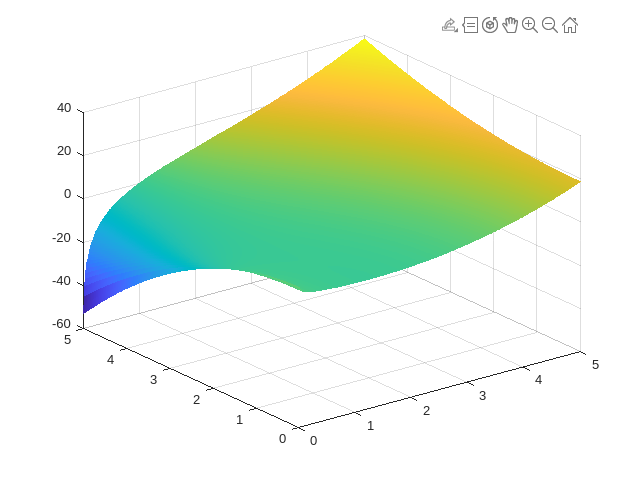

x2n = 0:0.01:5;
x1n = x2n;
[x1m,x2m] =meshgrid(x1n,x2n);
z = (x2m.^2/2+x1m.^2/2-1).*log(x2n/2+x1n/2);
mesh(x1m,x2m,z)